## Quantify overlap of distributions from mutants

First, get the data and set parameters for the plots of Figure 4. 

new_color_d1 = [0 84/255 147/255];%'#005493';
new_color_d2 = [149/255 177/255 231/255];%'#95B1E7';
new_color_m1 = [255/255 147/255 0];%'#FF9300';
new_color_m2 = [255/255 212/255 121/255];%'#FFD479';
new_color_all = [216/255 27/255 88/255];%[77/255 139/255 96/255];%'#4D8B60';
new_color_START = [216/255 27/255 88/255];%'#008F00';
new_color_div_d = [0/255, 77/255, 46/255];%[181/255 23/255 0];%'#B51700';
new_color_div_m = [117/255, 225/255, 225/255];%[152/255 59/255 201/255];%'#983BC9';
new_color_psg1_d = [0 0 0];%'#FFFFFF';
new_color_psg1_m = [146/255 146/255 146/255];%'#929292';
new_color_white = [1 1 1];

ax_label_size = 32;
ax_ticklabel_size = 28;
ax_line_width = 3;

line_width_thick = 4;
line_width_slim = 2;
face_alpha = 0.2;
legend_label_size = 28;
title_label_size = 34;

label_mutants = {'WT','+CV_{SS}','-CV_{SS}','+CV_{Start}','-CV_{Start}','Sizer','Timer','Random'};
label_mutants_tex = {'WT','+\nablaCV_{SS}','-\nablaCV_{SS}','+\nablaCV_{Start}','-\nablaCV_{Start}','G1 Sizer','G1 Timer','Random'};
label_mutants_latex = {'WT','$+\nablaCV_{SS}$','$-\nablaCV_{SS}$','$+\nablaCV_{Start}$','$-\nablaCV_{Start}$','G1 Sizer','G1 Timer','Random'};
n_mutants = length(label_mutants)-1;
x_mutants = 1:n_mutants;

D_js_MD_full = [0.32987,0.44974,0.18101,0.40832,0.19115,0.42817,0.17726];
D_js_D1D2_start = [0.08720,0.22152,0.01123,0.00303,0.47605,0.08252,0.09481];

cv_full_mutants = [0.40741,0.57815,0.33310,0.42683,0.47730,0.37618,0.51069];
cv_start_mutants = [0.23914,0.30542,0.23373,0.19097,0.39995,0.10792, 0.48320];

marker_mutants = {'o','^','v','^','v','D','D'};
marker_mutants_scatter = {'o','s','d','s','d','s','d'};
null_marker =  {'o','o','o','o','o','o','o'};

analysis_path = strcat(pwd,'/analysis/parameter_direction');%pwd;

## Plot the known PPVs

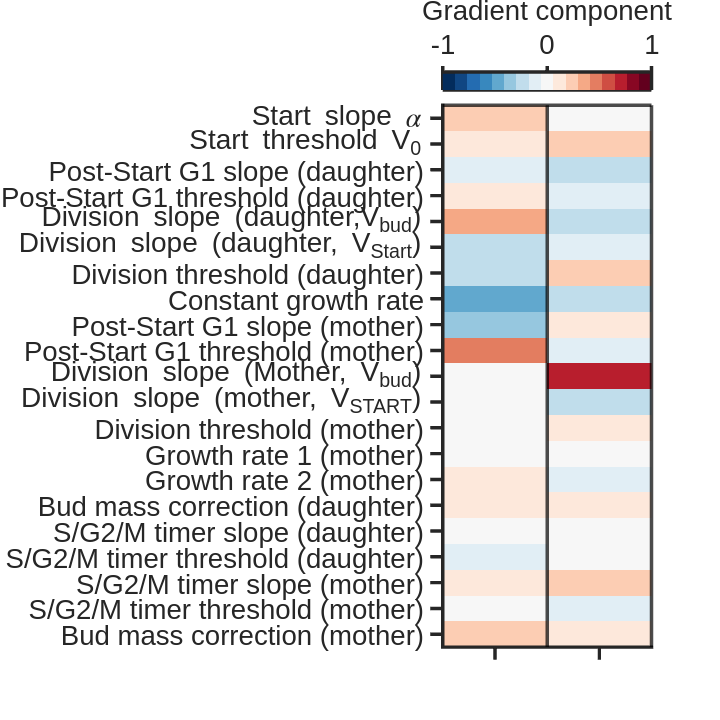


ppv_cv_full = flip([0.2,0.091,-0.12,0.16,0.38,-0.18,-0.18,-0.5,-0.35,0.5,0,0,0,0,0.12,0.06,0,-0.12,0.08,0,0.19]);
ppv_cv_start = flip([0,0.27,-0.26,-0.15,-0.26,-0.11,0.26,-0.25,0.12,-0.16,0.65,-0.25,0.13,0,-0.063,0.14,0,0,0.2,-0.074,0.12]);

ppv_plot = cat(1,ppv_cv_full,ppv_cv_start)';

row_labels = flip({'Start slope \alpha','Start threshold V_0','Post-Start G1 slope (daughter)','Post-Start G1 threshold (daughter)','Division slope (daughter,V_{bud})',...
    'Division slope (daughter, V_{Start})','Division threshold (daughter)','Constant growth rate','Post-Start G1 slope (mother)','Post-Start G1 threshold (mother)',...
    'Division slope (Mother, V_{bud})','Division slope (mother, V_{START})','Division threshold (mother)','Growth rate 1 (mother)','Growth rate 2 (mother)',...
    'Bud mass correction (daughter)','S/G2/M timer slope (daughter)',...
    'S/G2/M timer threshold (daughter)','S/G2/M timer slope (mother)','S/G2/M timer threshold (mother)','Bud mass correction (mother)'});

cmap = flipud(brewermap(11,'RdBu'));
%redbluecmap;
n_colors = 17;
newCmap = imresize(cmap, [n_colors, 3]);  % original color map contain just 11 colors, this increase it to 64
newCmap = min(max(newCmap, 0), 1);

ppv_plot_trunk = flip(ppv_plot);
for i = 1:length(row_labels)
    for k = 1:2
        if abs(ppv_plot_trunk(i,k)) < 0
            ppv_plot_trunk(i,k) = 0;
        end
    end
end

f = figure('Name','ppv_im','Position',[0 0 1200 1200]);


im = imagesc(ppv_plot_trunk,[-1,1]);
colormap(gca,newCmap)
hold on
c = colorbar;
c.Label.String = 'Gradient component';
set(c,'linewidth',ax_line_width)
set(c,'FontSize',ax_ticklabel_size-4)
set(c,'TickDir','out');
set(c,'TickLength',0.02);
set(c,'Location','NorthOutside')

yticks(1:length(row_labels))
yticklabels(flip(row_labels))
ylim([0.5 length(row_labels)+0.5])
%xlim([-0.6,0.7])
xticks([1,2])
xticklabels({'',''})
%xticklabels({'$\rm\vec{\nabla}CV_{SS}$','$\rm\vec{\nabla}CV_{Start}$'})
%title('Size Distribution - All Cells','Fontsize',title_label_size)
set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size-4)

set(gca,'TickDir','out');
set(gca,'TickLength',[0.02 0]);
set(gca,"Box",'off')
xline(gca().XLim(2),'LineWidth',ax_line_width,'Color','k')
yline(gca().YLim(1),'LineWidth',ax_line_width,'Color','k')
xline(1.5,'LineWidth',ax_line_width,'Color','k')

%grid on
%set(gca,'GridAlpha',0.08,'GridLineWidth',line_width_slim,'YGrid','off')
%saveas(gcf,strcat(analysis_path,'/ppv_all_image.png'))

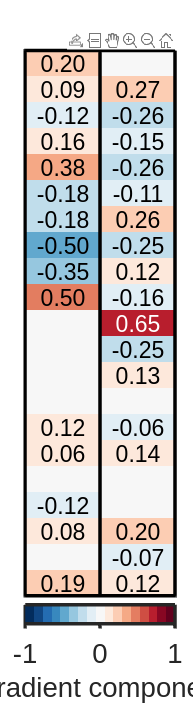

cmap = flipud(brewermap(11,'RdBu'));
%redbluecmap;
n_colors = 17;
newCmap = imresize(cmap, [n_colors, 3]);  % original color map contain just 11 colors, this increase it to 64
newCmap = min(max(newCmap, 0), 1);


ppv_plot_trunk = flip(ppv_plot);
for k = 1:2
    for i = 1:length(row_labels)
        if abs(ppv_plot_trunk(i,k)) < 0
            ppv_plot_trunk(i,k) = 0;
        end
    end
    ppv_plot_trunk(:,k) = ppv_plot_trunk(:,k)/norm(ppv_plot_trunk(:,k));
end

%ppv_plot_trunk = ppv_plot_trunk/norm(ppv_plot_trunk);

f = figure('Name','ppv_im','Position',[0 0 350 1300]);


im = imagesc(ppv_plot_trunk,[-1,1]);
colormap(gca,newCmap)
hold on
% Annotate the matrix
for i = 1:length(row_labels)
    for k = 1:2
        if ppv_plot_trunk(i,k) ~= 0
            if abs(ppv_plot_trunk(i,k)) > 0.55
                col = 'w';
            else
                col = 'k';
            end
            text(k,i,num2str(ppv_plot_trunk(i,k),'%.2f'),'HorizontalAlignment','center','Color',col,'Fontsize',20)
        end
    end
end

c = colorbar;
c.Label.String = 'Gradient component';
set(c,'linewidth',ax_line_width)
set(c,'FontSize',ax_ticklabel_size-4)
set(c,'TickDir','out');
set(c,'TickLength',0.02);
set(c,'Location','southOutside')

yticks(1:length(row_labels))
yticklabels(strings([1,length(row_labels)]))
ylim([0.5 length(row_labels)+0.5])
%xlim([-0.6,0.7])
xticks([1,2])
xticklabels({'',''})
%xticklabels({'$\rm\vec{\nabla}CV_{SS}$','$\rm\vec{\nabla}CV_{Start}$'})
%title('Size Distribution - All Cells','Fontsize',title_label_size)
set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size-4)

set(gca,'TickDir','out');
set(gca,'TickLength',[0.0 0]);
set(gca,"Box",'off')
xline(gca().XLim(2),'LineWidth',ax_line_width,'Color','k','Alpha',1)
yline(gca().YLim(1),'LineWidth',ax_line_width,'Color','k','Alpha',1)
xline(gca().XLim(1),'LineWidth',ax_line_width,'Color','k','Alpha',1)
yline(gca().YLim(2),'LineWidth',ax_line_width,'Color','k','Alpha',1)
xline(1.5,'LineWidth',ax_line_width,'Color','k','Alpha',1)

### Load the random ppvs to get the CV and the JS-Div

n_random = 30;

D_js_MD_full_random = [];%[0.275 0.272 0.336 0.315 0.323 0.359 0.245];
D_js_D1D2_start_random = [];%[0.110,0.091,0.193,0.086,0.153,0.046,0.007];
cv_full_random = [];%[0.441,0.392,0.407,0.416,0.406,0.461,0.355];
cv_start_random = [];%[0.281,0.254,0.236,0.248,0.252,0.255,0.213];

load_vars = {"cell_v","cell_bud","mother_daughter","M_D_at_birth_processed","volume_at_START"};

for z = 1:n_random
    %%% Load the workspace variables we need
    %%%%%%%%%%%%%%%%%%%%%%%% Change here as needed to load the correct workspaces!!!!!!!
    %%%%%%%%%%%%%%%%%%%%%%%% %%%%%%%%%%%%%%%%%%%%%%%%%
    clear(load_vars{:})
    load_path = strcat(pwd,'/sim_result/parameter_direction/random/ppv_',num2str(z));
    load(strcat(load_path,"/sim_workspace.mat"),load_vars{:})    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % Full distribution
    mean_size_full = mean(cell_v(:,length(cell_v(1,:))) + cell_bud(:,length(cell_v(1,:))));
    std_size_full = std(cell_v(:,length(cell_v(1,:))) + cell_bud(:,length(cell_v(1,:))));
    if mean_size_full ~= 0
        cv_size_full = std_size_full/mean_size_full;
    else
        cv_size_full = 0;
    end
    size_full_daughters = [];
    size_full_mothers = [];
    for i = 1:length(mother_daughter(:,end))
        if mother_daughter(i,end) == 1
            size_full_mothers(i) = cell_v(i,length(cell_v(1,:))) + cell_bud(i,length(cell_v(1,:)));    
        else
            size_full_daughters(i) = cell_v(i,length(cell_v(1,:))) + cell_bud(i,length(cell_v(1,:))); 
        end 
    end
    size_full_daughters = size_full_daughters(size_full_daughters~=0);
    size_full_mothers = size_full_mothers(size_full_mothers~=0);
    xmin = 0.25e1;
    xmax = 30e1;
    bins = xmin:2.16*xmin:xmax;
    [p_size_full_daughters,~] = histcounts((size_full_daughters)/1e3,bins,'Normalization','probability');
    [p_size_full_mothers,~] = histcounts((size_full_mothers)/1e3,bins,'Normalization','probability');
    JS_div_MD_full = JS_div(p_size_full_daughters,p_size_full_mothers);
    
    % Store relevant variables in array
    D_js_MD_full_random(z) = JS_div_MD_full;
    cv_full_random(z) = cv_size_full;

    % Daughter size at Start
    size_at_start_from_mother = [];
    size_at_start_from_daughter = [];
    
    for i = 1:length(M_D_at_birth_processed)
        if M_D_at_birth_processed(i) == 1
            size_at_start_from_mother(i) = volume_at_START(i);
        else
            size_at_start_from_daughter(i) = volume_at_START(i);
        end 
    end
    size_at_start_from_mother = size_at_start_from_mother(size_at_start_from_mother~=0);
    size_at_start_from_daughter = size_at_start_from_daughter(size_at_start_from_daughter~=0);
    
    mean_size_START = mean(volume_at_START);
    std_size_START = std(volume_at_START);
    if mean_size_START ~= 0
        cv_size_START = std_size_START/mean_size_START;
    else
        cv_size_START = 0;
    end
    xmin = 0.2e1;
    xmax = 20e1;
    bins_START = xmin:2.5*xmin:xmax;
    
    [p_size_start_from_daughters,~] = histcounts(size_at_start_from_daughter/1e3,bins_START,'Normalization','probability');
    [p_size_start_from_mothers,~] = histcounts(size_at_start_from_mother/1e3,bins_START,'Normalization','probability');
    JS_div_D1D2_start = JS_div(p_size_start_from_daughters,p_size_start_from_mothers);

    % Store relevant variables in array
    D_js_D1D2_start_random(z) = JS_div_D1D2_start;
    cv_start_random(z) = cv_size_START;
end

Error using load
Unable to find file or directory '/home/felix/Documents/Codes/codes_for_submission/sim_result/parameter_direction/random/ppv_1/sim_workspace.mat'.

## Mother/Daughter Full Size Distribution Overlap, plot with p-values as colors

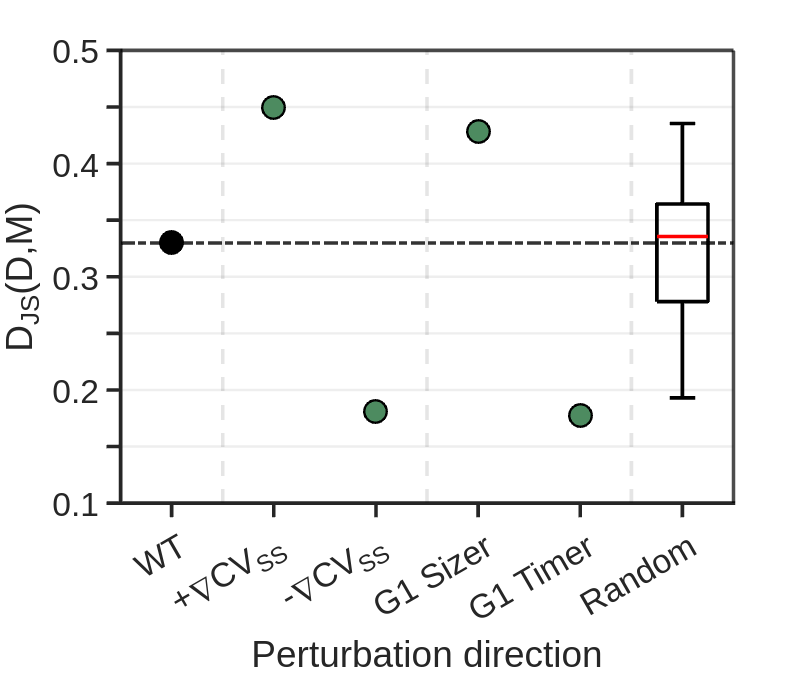

label_mutants_tex_short_ss = {'WT','+\nablaCV_{SS}','-\nablaCV_{SS}','G1 Sizer','G1 Timer','Random'};

n_mutants_short_ss = length(label_mutants_tex_short_ss)-1;
x_mutants_short_ss = 1:n_mutants_short_ss;

D_js_MD_full_short_ss(1:3) = D_js_MD_full(1:3);
D_js_MD_full_short_ss(4:5) = D_js_MD_full(6:7);

p_val_D_js_MD_full_short_ss = [];
format shortE
for i = 1:n_mutants_short_ss
    [h,p_val_D_js_MD_full_short_ss(i)] = ttest(D_js_MD_full_random,D_js_MD_full_short_ss(i),'Alpha',0.01);
end

figure('Name','Mutant overlap in MD Full Distribution Short SS','Position', [0 0 900 750])

xline(1.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
hold on
xline(3.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
xline(5.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
%xline(7.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
bl = yline(D_js_MD_full_short_ss(1),'color','k','Linestyle','-.','LineWidth',ax_line_width,'Alpha',0.8);

for i = 1:n_mutants_short_ss
    if p_val_D_js_MD_full_short_ss(i) < 0.01
        col = new_color_all;
    elseif i == 1
        col = 'k';
    else
        col = 'w';
    end
    s = scatter(x_mutants_short_ss(i),D_js_MD_full_short_ss(i),350,col,'Filled','MarkerFaceAlpha',1, ...
    'MarkerEdgeColor','k','LineWidth',ax_line_width-1,'Marker',null_marker(i));
    uistack(s,'top')
end


%s = swarmchart((n_mutants+1)*ones(n_random),D_js_MD_full_random,100, ...
%    'MarkerFaceColor','#d3d3d3','MarkerEdgeColor','k','LineWidth',ax_line_width-1, ...
%    'XJitterWidth',0.4);
b = boxplot(D_js_MD_full_random,'Positions',n_mutants_short_ss+1,'BoxStyle','outline','Colors','k','Widths',0.5);
set(b,'LineWidth',ax_line_width,'LineStyle','-')
plot([n_mutants_short_ss+0.75,n_mutants_short_ss+1.25],[median(D_js_MD_full_random),median(D_js_MD_full_random)],'LineWidth',ax_line_width,'Color','r')


xticks(1:n_mutants_short_ss+1)
xticklabels(label_mutants_tex_short_ss)
set(gca,'TickLabelInterpreter','tex');

ylabel('D_{JS}(D,M)','FontSize',ax_label_size,'Interpreter','tex')
xlabel('Perturbation direction','FontSize',ax_label_size)
xlim([0.5,n_mutants_short_ss+1.5])

ylim([0.1,0.5])
yticks(0.1:0.05:0.5)
yticklabels({'0.1','','0.2','','0.3','','0.4','','0.5'})

% Format axis
set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size)
set(gca,'TickDir','out');
set(gca,'TickLength',[0.02 0]);

% Turn off axis on the right and top axis
set(gca,"Box",'off')
xline(gca().XLim(2),'LineWidth',ax_line_width,'Color','k')
yline(gca().YLim(2),'LineWidth',ax_line_width,'Color','k')
%xlim([x(1), x(end)])
%ylim([y(1), y(end)])

%title('Overlap between Mother and Daughter Full size distributions','FontSize',title_label_size-1)
grid on
set(gca,'GridAlpha',0.08,'GridLineWidth',line_width_slim,'XGrid','off')
%saveas(gcf,strcat(analysis_path,'/full_size_dist_overlap_boxplot_short.png'))

## Mother/Daughter steady-state Size Distribution CV, plot with p-values as colors

%label_mutants_tex_short_ss = {'WT','+\nablaCV_{SS}','-\nablaCV_{SS}','G1 Sizer','G1 Timer','Random'};

%n_mutants_short_ss = length(label_mutants_tex_short_ss)-1;
%x_mutants_short_ss = 1:n_mutants_short_ss;

cv_full_mutants_short_ss(1:3) = cv_full_mutants(1:3);
cv_full_mutants_short_ss(4:5) = cv_full_mutants(6:7);

p_val_cv_full_short_ss = [];
format shortE

for i = 1:n_mutants_short_ss
    [h,p_val_cv_full_short_ss(i)] = ttest(cv_full_random/cv_full_mutants_short_ss(1),cv_full_mutants_short_ss(i)/cv_full_mutants_short_ss(1),'Alpha',0.01);
end


figure('Name','CV Full Distribution for mutants','Position', [0 0 900 750])

xline(1.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
hold on
xline(3.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
xline(5.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
%xline(7.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
bl = yline(cv_full_mutants_short_ss(1)/cv_full_mutants_short_ss(1),'color','k','Linestyle','-.','LineWidth',ax_line_width,'Alpha',0.8);
uistack(bl,'bottom')

for i = 1:n_mutants_short_ss
    if p_val_cv_full_short_ss(i) < 0.01
        col = new_color_all;
    elseif i == 1
        col = 'k'; 
    else
        col = 'w';
    end
    s = scatter(x_mutants_short_ss(i),cv_full_mutants_short_ss(i)/cv_full_mutants_short_ss(1),350,col,'Filled','MarkerFaceAlpha',1, ...
    'MarkerEdgeColor','k','LineWidth',ax_line_width-1,'Marker',null_marker(i));
    uistack(s,'top')
end

%s = swarmchart((n_mutants+1)*ones(n_random),cv_full_random/cv_full_mutants(1),100, ...
%    'MarkerFaceColor','#d3d3d3','MarkerEdgeColor','k','LineWidth',ax_line_width-1, ...
%    'XJitterWidth',0.4);
b = boxplot(cv_full_random/cv_full_mutants_short_ss(1),'Positions',n_mutants_short_ss+1,'BoxStyle','outline','Colors','k','Widths',0.5,'OutlierSize',10,'Symbol','o');
set(b,'LineWidth',ax_line_width,'LineStyle','-')
plot([n_mutants_short_ss+0.75,n_mutants_short_ss+1.25],[median(cv_full_random/cv_full_mutants_short_ss(1)),median(cv_full_random/cv_full_mutants_short_ss(1))],'LineWidth',ax_line_width,'Color','r')
uistack(b,'top')

xticks(1:n_mutants_short_ss+1)
xticklabels(label_mutants_tex_short_ss)
set(gca,'TickLabelInterpreter','tex');

ylabel('Relative CV_{SS}','Interpreter','tex','FontSize',ax_label_size)
xlabel('Perturbation direction','FontSize',ax_label_size)
xlim([0.5,n_mutants_short_ss+1.5])

%ylim([0.25,0.65])
%yticks(0.25:0.05:0.65)
ylim([0.6,1.6])
yticks(0.4:0.1:1.6)
yticklabels({'0.4','','0.6','','0.8','','1','','1.2','','1.4','','1.6'})

set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size)
set(gca,'TickDir','out');
set(gca,'TickLength',[0.02 0]);
%box on
set(gca,"Box",'off')
xline(gca().XLim(2),'LineWidth',ax_line_width,'Color','k')
yline(gca().YLim(2),'LineWidth',ax_line_width,'Color','k')

grid on
set(gca,'GridAlpha',0.08,'GridLineWidth',line_width_slim,'XGrid','off')
%title('CV of steady-state size distributions','FontSize',title_label_size-1)
%saveas(gcf,strcat(analysis_path,'/full_size_dist_cv_rel_boxplot_short.png'))

## Daughter 1st gen./Daughter 2nd gen. overlap at START, colors with p-values compared to random ppv

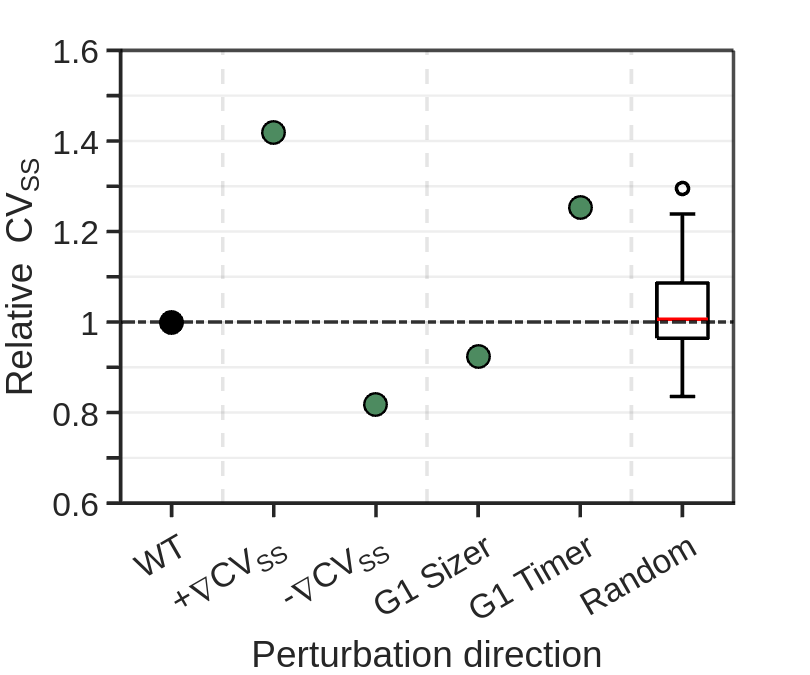

label_mutants_tex_short_start = {'WT','+\nablaCV_{Start}','-\nablaCV_{Start}','G1 Sizer','G1 Timer','Random'};

n_mutants_short_start = length(label_mutants_tex_short_start)-1;
x_mutants_short_start = 1:n_mutants_short_start;

D_js_D1D2_start_short_start(1) = D_js_D1D2_start(1);
D_js_D1D2_start_short_start(2:5) = D_js_D1D2_start(4:7);

cv_start_mutants_short_start(1) = cv_start_mutants(1);
cv_start_mutants_short_start(2:5) = cv_start_mutants(4:7);

p_val_D_js_D1D2_start_short_start = [];
format shortE

for i = 1:n_mutants_short_start
    [h,p_val_D_js_D1D2_start_short_start(i)] = ttest(D_js_D1D2_start_random,D_js_D1D2_start_short_start(i),'Alpha',0.01);
end


figure('Name','Mutant overlap in D1D2 Start Distribution','Position', [0 0 900 750])
xline(1.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
hold on
xline(3.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
xline(5.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
%xline(7.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
bl = yline(D_js_D1D2_start(1),'color','k','Linestyle','-.','LineWidth',ax_line_width,'Alpha',0.8);
uistack(bl,'bottom')

for i = 1:n_mutants_short_start
    if p_val_D_js_D1D2_start_short_start(i) < 0.01
        col = new_color_all;
    elseif i == 1
        col = 'k'; 
    else
        col = 'w';
    end
    s = scatter(x_mutants_short_start(i),D_js_D1D2_start_short_start(i),350,col,'Filled','MarkerFaceAlpha',1, ...
    'MarkerEdgeColor','k','LineWidth',ax_line_width-1,'Marker','o');
    uistack(s,'top');
    if i == 1
        hold on
    end
end

%s = swarmchart((n_mutants+1)*ones(n_random),D_js_D1D2_start_random,100, ...
%    'MarkerFaceColor','#d3d3d3','MarkerEdgeColor','k','LineWidth',ax_line_width-1, ...
%    'XJitterWidth',0.4);
b = boxplot(D_js_D1D2_start_random,'Positions',n_mutants_short_start+1,'BoxStyle','outline','Colors','k','Widths',0.5,'OutlierSize',10,'Symbol','o');
uistack(b,'top')
set(b,'LineWidth',ax_line_width,'LineStyle','-')
plot([n_mutants_short_start+0.75,n_mutants_short_start+1.25],[median(D_js_D1D2_start_random),median(D_js_D1D2_start_random)],'LineWidth',ax_line_width,'Color','r')

xticks(1:n_mutants_short_start+1)
xticklabels(label_mutants_tex_short_start)
set(gca,'TickLabelInterpreter','tex');

ylabel('D_{JS}(D_{1},D_{2+})','FontSize',ax_label_size)
xlabel('Perturbation direction','FontSize',ax_label_size)
xlim([0.5,n_mutants_short_start+1.5])

ylim([-0.05,0.6])
yticks(-0.1:0.1:0.6)
%ylim([-0.5,6.5])
%yticks(-0.5:0.5:6.5)
%yticklabels({'','0','','1','','2','','3','','4','','5','','6',''})

set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size)
set(gca,'TickDir','out');
set(gca,'TickLength',[0.02 0]);

set(gca,"Box",'off')
xline(gca().XLim(2),'LineWidth',ax_line_width,'Color','k')
yline(gca().YLim(2),'LineWidth',ax_line_width,'Color','k')

%box on
grid on
set(gca,'GridAlpha',0.08,'GridLineWidth',line_width_slim,'XGrid','off')
%title('Overlap 1st and 2nd gen. daughters at START','FontSize',title_label_size-1)
%saveas(gcf,strcat(analysis_path,'/start_size_dist_overlap_boxplot_short.png'))

## Daughter 1st gen./Daughter 2nd gen. CV of size at START, colors with p-values compared to random ppv

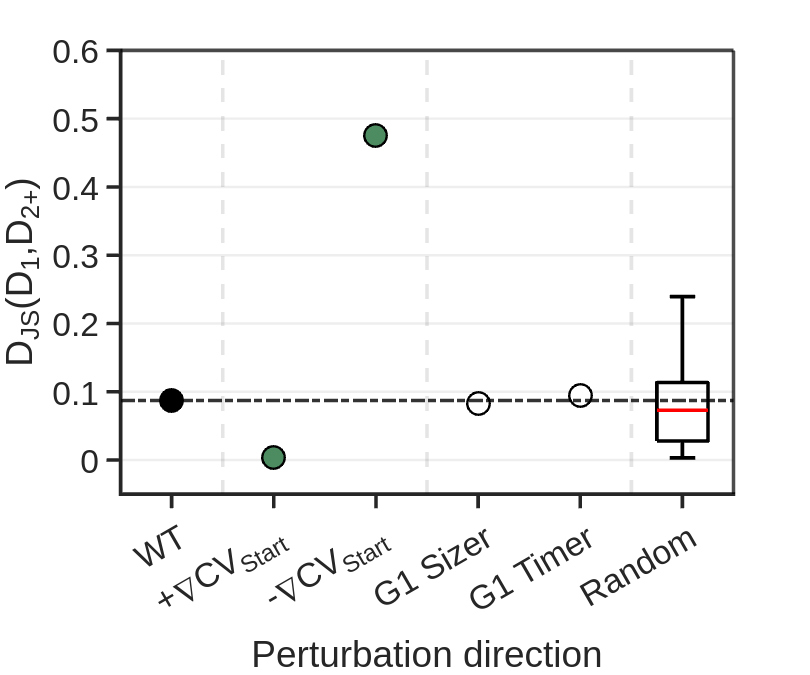


p_val_cv_start_short_start = [];
format shortE


for i = 1:n_mutants_short_start
    [h,p_val_cv_start_short_start(i)] = ttest(cv_start_random/cv_start_mutants_short_start(1),cv_start_mutants_short_start(i)/cv_start_mutants_short_start(1),'Alpha',0.01);
end


figure('Name','CV START Distribution for mutants','Position', [0 0 900 750])
xline(1.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
hold on
xline(3.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
xline(5.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
%xline(7.5,'color','k','LineStyle','--','LineWidth',ax_line_width,'Alpha',0.1)
bl = yline(cv_start_mutants(1)/cv_start_mutants(1),'color','k','Linestyle','-.','LineWidth',ax_line_width,'Alpha',1);
uistack(bl,'bottom')

for i = 1:n_mutants_short_start
    if p_val_cv_start_short_start(i) < 0.01
        col = new_color_all;
    elseif i == 1
        col = 'k'; 
    else
        col = 'w';
    end
    s = scatter(x_mutants_short_start(i),cv_start_mutants_short_start(i)/cv_start_mutants_short_start(1),350,col,'Filled','MarkerFaceAlpha',1, ...
    'MarkerEdgeColor','k','LineWidth',ax_line_width-1,'Marker','o');
    uistack(s,'top')
end

%s = swarmchart((n_mutants+1)*ones(n_random),cv_start_random/cv_start_mutants(1),100, ...
%    'MarkerFaceColor','#d3d3d3','MarkerEdgeColor','k','LineWidth',ax_line_width-1, ...
%    'XJitterWidth',0.4);
b = boxplot(cv_start_random/cv_start_mutants_short_start(1),'Positions',n_mutants_short_start+1,'BoxStyle','outline','Colors','k','Widths',0.5,'OutlierSize',10,'Symbol','o');
set(b,'LineWidth',ax_line_width,'LineStyle','-')
uistack(b,'top')
plot([n_mutants_short_start+0.75,n_mutants_short_start+1.25],[median(cv_start_random/cv_start_mutants_short_start(1)),median(cv_start_random/cv_start_mutants_short_start(1))],'LineWidth',ax_line_width,'Color','r')

xticks(1:n_mutants_short_start+1)
xticklabels(label_mutants_tex_short_start)
set(gca,'TickLabelInterpreter','tex');

ylabel('Relative CV_{Start}','FontSize',ax_label_size)
xlabel('Perturbation direction','FontSize',ax_label_size)
xlim([0.5,n_mutants_short_start+1.5])

%ylim([0.15,0.45])
%yticks(0.15:0.05:0.45)
ylim([0.2,2.4])
yticks(0.2:0.2:2.4)
yticklabels({'0.2','','0.6','','1.0','','1.4','','1.8','','2.2','','2.6','','3.0'})

set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size)
set(gca,'TickDir','out');
set(gca,'TickLength',[0.02 0]);

set(gca,"Box",'off')
xline(gca().XLim(2),'LineWidth',ax_line_width,'Color','k')
yline(gca().YLim(2),'LineWidth',ax_line_width,'Color','k')

%box on
grid on
set(gca,'GridAlpha',0.08,'GridLineWidth',line_width_slim,'XGrid','off')
%title('CV of START size distributions','FontSize',title_label_size-1)
%saveas(gcf,strcat(analysis_path,'/start_size_dist_cv_rel_boxplot_short.png'))

### Scatter plot of the CV as a function of the asymmetry between subpopulations

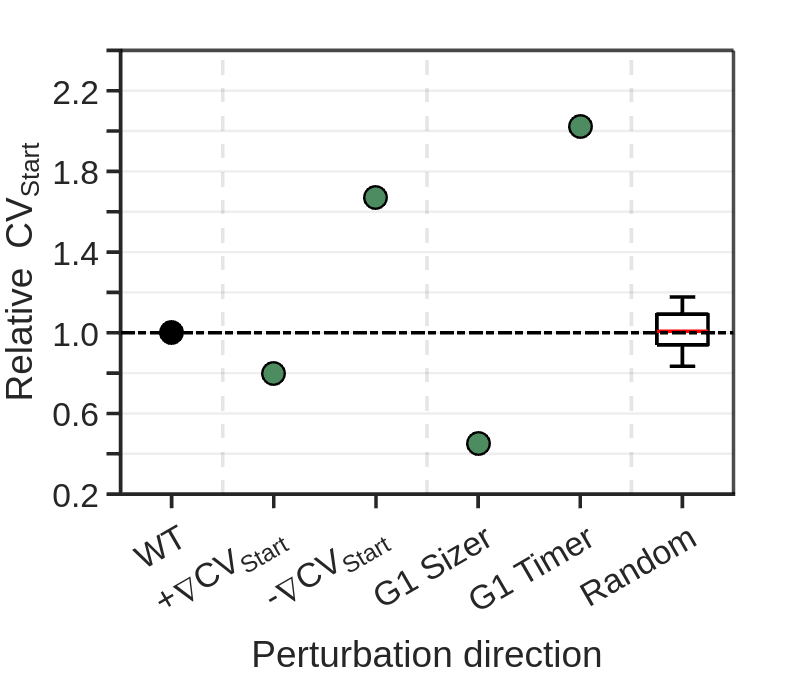

movie_mutants = {'\itcln3\Delta', '\itcln3\Deltawhi5\Delta'}; %{'cln3', 'cln3whi5', 'ccr4', 'ccr4whi5', 'WT Glucose'}
JS_div_Start_movie_mutants = [0.15674634, 0.2428121];%[0.15674634, 0.2428121, 0.54787714, 0.53530227, 0.3722267 ]
cv_start_movie_mutants = [0.33892358, 0.38066647];%[0.33892358, 0.38066647, 0.48371264, 0.4080736,  0.21865035]
JS_div_full_movie_mutants = [0.4842642,  0.46608195];%[0.4842642,  0.46608195, 0.37477717, 0.46102243, 0.37788624]
cv_full_movie_mutants = [0.44643073, 0.51962869];%[0.44643073, 0.51962869, 0.54171277, 0.46726415, 0.31499645]
color_movie_mutants = [new_color_d1',new_color_d2'];%[new_color_d1',new_color_d2',new_color_m1',new_color_m2',new_color_div_m']

new_color_brown = [225/256, 193/256, 110/256];
color_mutants = [new_color_psg1_d',new_color_div_d',new_color_div_d',new_color_START',new_color_START',new_color_psg1_d',new_color_white'];

figure('Name','CV Full vs D_JS(M,D)','Position', [0 0 950 900])
hold on
s = scatter(D_js_MD_full_random,cv_full_random,300,'MarkerFaceColor','#d3d3d3','MarkerEdgeColor','k','LineWidth',ax_line_width-1);
uistack(s,'bottom')
h(2) = plot(nan,nan,'bo','MarkerSize',20,'DisplayName','Random',... 
        'Marker','o','MarkerEdgeColor','k','MarkerFaceColor','#d3d3d3', ...
        'LineWidth',ax_line_width-1);

for i = 1:n_mutants
    if rem(i,2)==0 
        size = 400;
    else
        size = 400;
    end
    s = scatter(D_js_MD_full(i),cv_full_mutants(i),size,color_mutants(:,i)','Filled','MarkerFaceAlpha',1, ...
    'MarkerEdgeColor','k','LineWidth',ax_line_width-1,'Marker',marker_mutants(i));
    uistack(s,'top')
    if i == 1
        h(1) = plot(nan,nan,'bo','MarkerSize',size/23,'DisplayName',label_mutants_tex{i},... 
        'Marker',marker_mutants(i),'MarkerEdgeColor','k','MarkerFaceColor',color_mutants(:,i)', ...
        'LineWidth',ax_line_width-1);
    else    
        h(i+1) = plot(nan,nan,'bo','MarkerSize',size/23,'DisplayName',label_mutants_tex{i},... 
        'Marker',marker_mutants(i),'MarkerEdgeColor','k','MarkerFaceColor',color_mutants(:,i)', ...
        'LineWidth',ax_line_width-1);
    end
end

for i = 1:length(movie_mutants)
    s = scatter(JS_div_full_movie_mutants(i),cv_full_movie_mutants(i),600,color_movie_mutants(:,i)','Filled','MarkerFaceAlpha',1, ...
    'MarkerEdgeColor','k','LineWidth',ax_line_width-1,'Marker','s');
    uistack(s,'top')
    h(i+n_mutants+1) = plot(nan,nan,'bo','MarkerSize',20,'DisplayName',movie_mutants{i},... 
        'Marker','s','MarkerEdgeColor','k','MarkerFaceColor',color_movie_mutants(:,i)', ...
        'LineWidth',ax_line_width-1);
end


yy = yline(cv_full_mutants(1),'--','LineWidth',ax_line_width,'Color','k','Alpha',0.4);
xx = xline(D_js_MD_full(1),'--','LineWidth',ax_line_width,'Color','k','Alpha',0.4);
uistack(yy,'bottom')
uistack(xx,'bottom')

ylabel('CV_{SS}','FontSize',ax_label_size)
xlabel('D_{JS}(D,M)','FontSize',ax_label_size)

xlim([0.1 0.55])
ylim([0.2 0.7])

set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size)
set(gca,'TickDir','out');
set(gca,'TickLength',[0.02 0]);
%box on
set(gca,"Box",'off')
xline(gca().XLim(2),'LineWidth',ax_line_width,'Color','k')
yline(gca().YLim(2),'LineWidth',ax_line_width,'Color','k')

grid on
set(gca,'GridAlpha',0.2,'GridLineWidth',line_width_slim)


l = legend(h,'NumColumns',5,'Location','Northoutside');


set(l,'LineWidth',1,'EdgeColor',new_color_psg1_m)
saveas(gcf,strcat(analysis_path,'/cv_full_vs_asymmetry_scatter_moviemutants_lite.png'))

Same for Start distribution

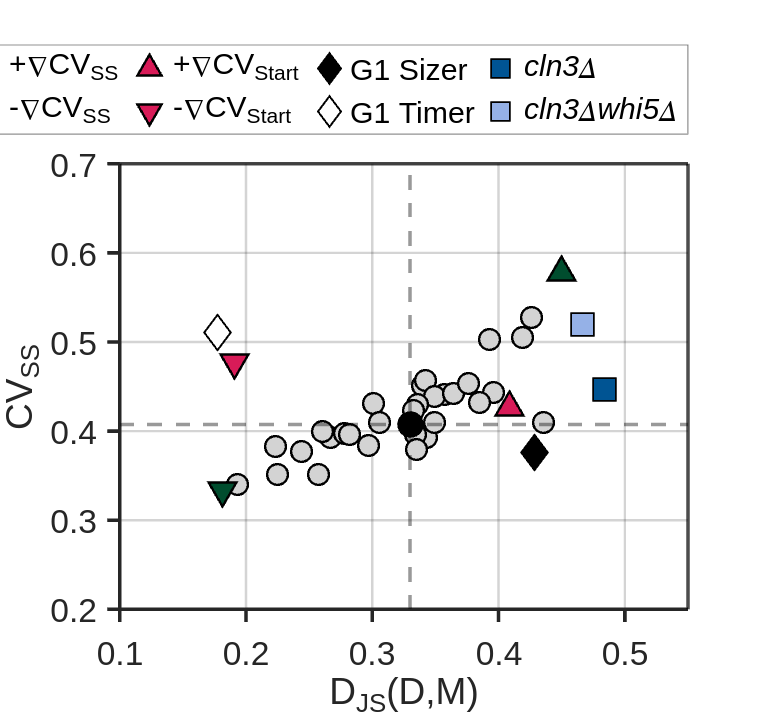

%marker_mutants_scatter = {'o','s','d','s','d','s','d'};

figure('Name','CV Start vs D_JS(D1,D2+)','Position', [0 0 950 900])
clear h
hold on

s = scatter(D_js_D1D2_start_random,cv_start_random,300,'MarkerFaceColor','#d3d3d3','MarkerEdgeColor','k','LineWidth',ax_line_width-1,'MarkerFaceAlpha',1);
uistack(s,'bottom')
h(2) = plot(nan,nan,'bo','MarkerSize',20,'DisplayName','Random',... 
        'Marker','o','MarkerEdgeColor','k','MarkerFaceColor','#d3d3d3', ...

        'LineWidth',ax_line_width-1);  

for i = 1:n_mutants
    if rem(i,2)==0 
        size = 400;
    else
        size = 400;
    end
    s = scatter(D_js_D1D2_start(i),cv_start_mutants(i),size,color_mutants(:,i)','Filled','MarkerFaceAlpha',1, ...
    'MarkerEdgeColor','k','LineWidth',ax_line_width-1,'Marker',marker_mutants(i));
    uistack(s,'top')
    if i == 1
        h(1) = plot(nan,nan,'bo','MarkerSize',size/23,'DisplayName',label_mutants_tex{i},... 
        'Marker',marker_mutants(i),'MarkerEdgeColor','k','MarkerFaceColor',color_mutants(:,i)', ...
        'LineWidth',ax_line_width-1);
    else
        h(i+1) = plot(nan,nan,'bo','MarkerSize',size/23,'DisplayName',label_mutants_tex{i},... 
        'Marker',marker_mutants(i),'MarkerEdgeColor','k','MarkerFaceColor',color_mutants(:,i)', ...
        'LineWidth',ax_line_width-1);
    end
end

for i = 1:length(movie_mutants)
    s = scatter(JS_div_Start_movie_mutants(i),cv_start_movie_mutants(i),600,color_movie_mutants(:,i)','Filled','MarkerFaceAlpha',1, ...
    'MarkerEdgeColor','k','LineWidth',ax_line_width-1,'Marker','s');
    uistack(s,'top')
    h(i+n_mutants+1) = plot(nan,nan,'bo','MarkerSize',20,'DisplayName',movie_mutants{i},... 
        'Marker','s','MarkerEdgeColor','k','MarkerFaceColor',color_movie_mutants(:,i)', ...
        'LineWidth',ax_line_width-1);
end

yy = yline(cv_start_mutants(1),'--','LineWidth',ax_line_width,'Color','k','Alpha',0.6);
uistack(yy,'bottom')
xx = xline(D_js_D1D2_start(1),'--','LineWidth',ax_line_width,'Color','k','Alpha',0.6);
uistack(xx,'bottom')
ylabel('CV_{Start}','FontSize',ax_label_size)
xlabel('D_{JS}(D_1,D_{2+})','FontSize',ax_label_size)

xlim([-0.05 0.6])
ylim([0 0.6])

set(gca,'linewidth',ax_line_width)
set(gca,'FontSize',ax_ticklabel_size)
set(gca,'TickDir','out');
set(gca,'TickLength',[0.02 0]);
set(gca,"Box",'off')
xline(gca().XLim(2),'LineWidth',ax_line_width,'Color','k')
yline(gca().YLim(2),'LineWidth',ax_line_width,'Color','k')

%box on
grid on
set(gca,'GridAlpha',0.2,'GridLineWidth',line_width_slim)


l = legend(h,'NumColumns',5,'Location','northoutside');


set(l,'LineWidth',1,'EdgeColor',new_color_psg1_m)
saveas(gcf,strcat(analysis_path,'/cv_start_vs_asymmetry_scatter_moviemutants_lite.png'))

### KL divergence

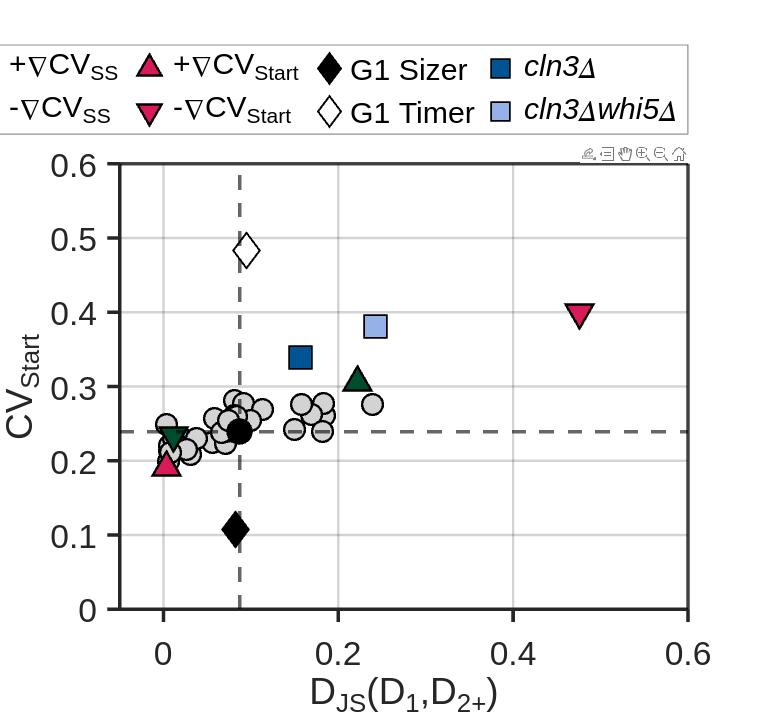

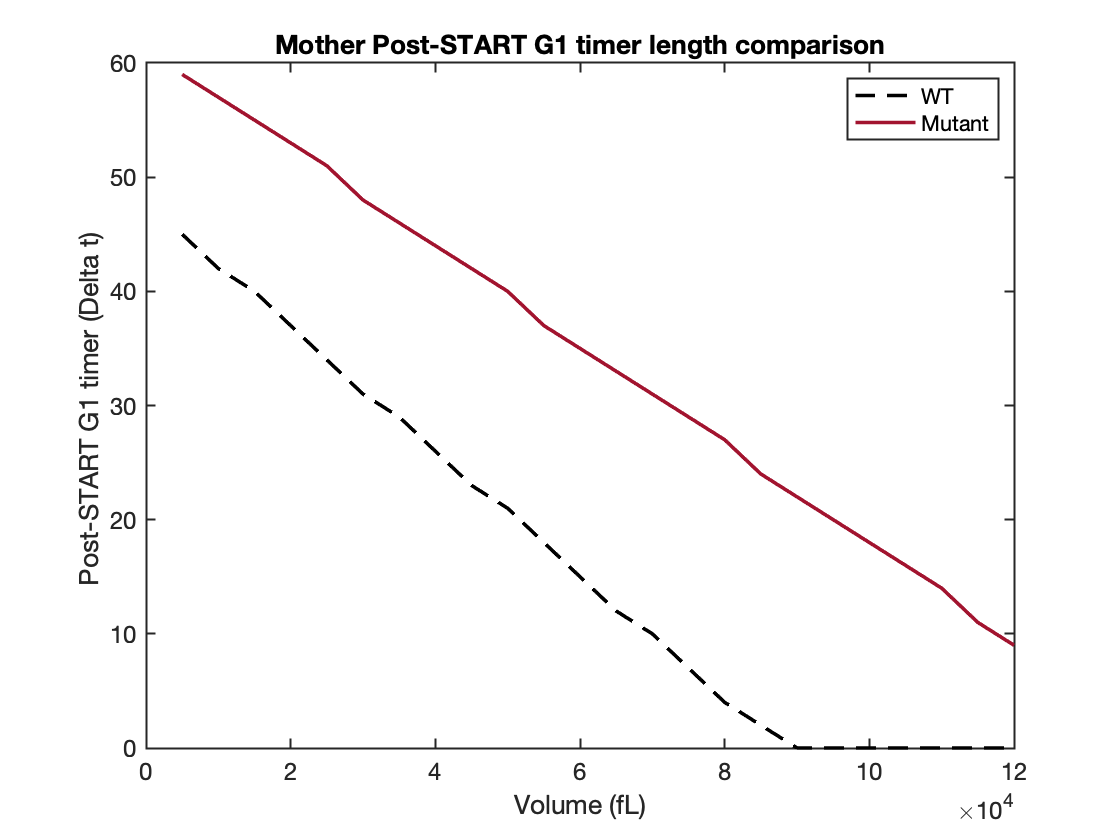

function div = KL_div(p,q)
    div = 0;
    for i = 1:length(p)
        if p(i) == 0
            continue
        elseif q(i) == 0
            disp('Problem with Q(i) == 0, review validity')
            break
        else
            div = div + p(i)*log2(p(i)/q(i));
        end
    end

end

### Jensen-Shannon Divergence

function div2 = JS_div(p,q)
    m = 0.5*(p+q);
    div2 = 0.5*KL_div(p(m~=0),m(m~=0)) + 0.5*KL_div(q(m~=0),m(m~=0));
end

